# Steg 1.1 – Plotta TRC-kurvor och bedöm neutrala färger

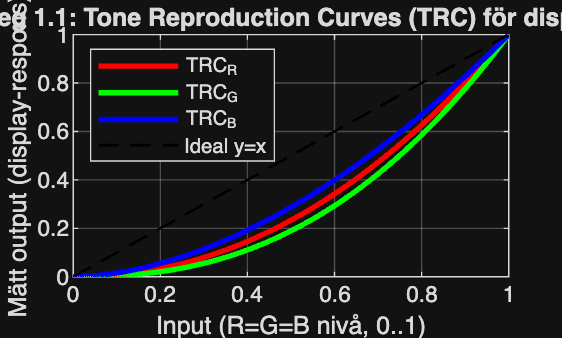

clear; clc;

% Ladda TRC-data
load('TRC_display.mat');   % innehåller TRCr, TRCg, TRCb

% Inputnivåer enligt labben
x = (0:0.01:1)';

% Plotta TRC för R, G, B + ideal linjär respons
figure;
plot(x, TRCr(:), 'r', 'LineWidth', 2); hold on;
plot(x, TRCg(:), 'g', 'LineWidth', 2);
plot(x, TRCb(:), 'b', 'LineWidth', 2);
plot(x, x, 'k--', 'LineWidth', 1);

grid on;
xlabel('Input (R=G=B nivå, 0..1)');
ylabel('Mätt output (display-respons)');
title('Steg 1.1: Tone Reproduction Curves (TRC) för display');
legend('TRC_R','TRC_G','TRC_B','Ideal y=x','Location','NorthWest');

## Steg 1.2 – Linearisering med invers TRC

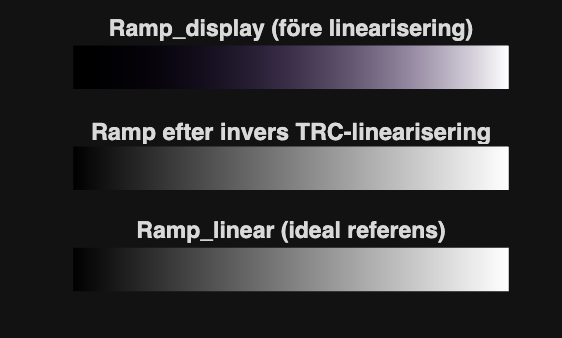

% Ladda ramp-data
load('Ramp_display.mat');   % okalibrerad ramp
load('Ramp_linear.mat');    % ideal linjär ramp (referens)

% Skapa tom bild för linjär ramp
Ramp_trc = zeros(size(Ramp_display));

% Gå igenom varje kanal separat
for c = 1:3
    if c == 1
        TRC = TRCr(:);
    elseif c == 2
        TRC = TRCg(:);
    else
        TRC = TRCb(:);
    end

    % Invers TRC med interpolering
    % interp1(x, TRC, y) → hittar vilket x som ger output y
    Ramp_trc(:,:,c) = interp1(TRC, x, Ramp_display(:,:,c),'linear', 'extrap');
end

% Se till att värdena ligger inom [0,1]
Ramp_trc = min(max(Ramp_trc, 0), 1);

%% Visa resultatet
figure;
subplot(3,1,1);
imshow(Ramp_display);
title('Ramp\_display (före linearisering)');

subplot(3,1,2);
imshow(Ramp_trc);
title('Ramp efter invers TRC-linearisering');

subplot(3,1,3);
imshow(Ramp_linear);
title('Ramp\_linear (ideal referens)');

## Steg 1.3 – Linearisering med gamma-korrigering

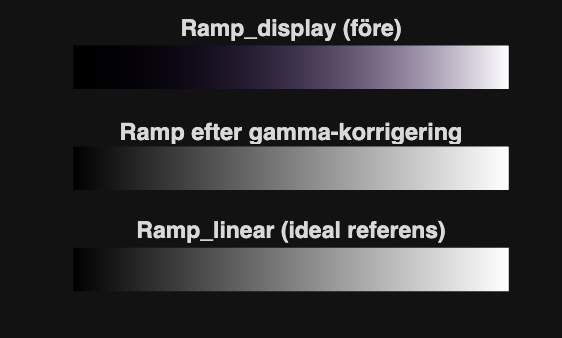

load('Ramp_display.mat');
load('Ramp_linear.mat');

% Gamma-värden från labben
gammaR = 2.1;
gammaG = 2.4;
gammaB = 1.8;

Ramp_gamma = zeros(size(Ramp_display));

% Kompensera varje kanal: x' = x^(1/gamma)
Ramp_gamma(:,:,1) = Ramp_display(:,:,1).^(1/gammaR);
Ramp_gamma(:,:,2) = Ramp_display(:,:,2).^(1/gammaG);
Ramp_gamma(:,:,3) = Ramp_display(:,:,3).^(1/gammaB);

% (säkerhet) klipp inom [0,1]
Ramp_gamma = min(max(Ramp_gamma, 0), 1);

% Visa jämförelsen
figure;
subplot(3,1,1);
imshow(Ramp_display);
title('Ramp\_display (före)');

subplot(3,1,2);
imshow(Ramp_gamma);
title('Ramp efter gamma-korrigering');

subplot(3,1,3);
imshow(Ramp_linear);
title('Ramp\_linear (ideal referens)');

## 2.1 – Plotta DLP-projektorns primärspektra (R, G, B)

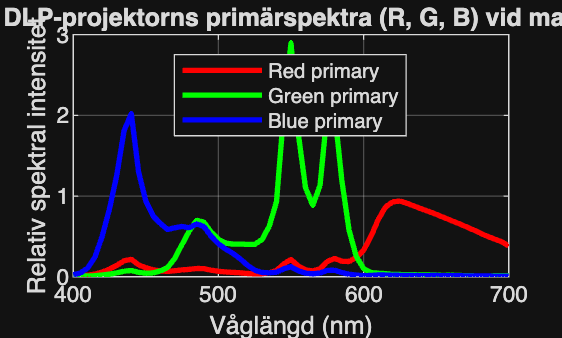

load('DLP.mat');      % DLP: 61x3 (spektra för R,G,B)
load('illum.mat');    % innehåller oftast waverange = 400:5:700

wl = double(waverange(:));   % 61x1 våglängder (nm)

figure;
plot(wl, DLP(:,1), 'r', 'LineWidth', 2); hold on;
plot(wl, DLP(:,2), 'g', 'LineWidth', 2);
plot(wl, DLP(:,3), 'b', 'LineWidth', 2);

grid on;
xlabel('Våglängd (nm)');
ylabel('Relativ spektral intensitet');
title('DLP-projektorns primärspektra (R, G, B) vid max');
legend('Red primary','Green primary','Blue primary','Location','best');

## 2.2

% Ladda data
load('DLP.mat');        % DLP: 61x3 (primärspektra)
load('RGB_raw.mat');    % RGB_raw: 3x20
load('XYZ_ref.mat');    % XYZ_ref: 3x20
load('xyz.mat');        % xyz: 61x3 (xbar ybar zbar)
load('illum.mat');      % innehåller CIED65 och waverange

dL = 5;

E = CIED65(:);                  % 61x1
ybar = xyz(:,2);

% Normalisering (samma princip som i Lab 1)
k = 100 / sum(E .* ybar * dL);

%Skapa spektra för varje patch (61x20)
S_raw = DLP * RGB_raw;       

% Spektrum -> XYZ (3x20)
XYZ_out = k * (xyz' * S_raw) * dL;

% XYZ -> Lab (med given xyz2lab.m)
[Lr, ar, br] = xyz2lab(XYZ_ref(1,:), XYZ_ref(2,:), XYZ_ref(3,:));
[Lo, ao, bo] = xyz2lab(XYZ_out(1,:), XYZ_out(2,:), XYZ_out(3,:));

% 4) DeltaEab
dE = sqrt((Lr-Lo).^2 + (ar-ao).^2 + (br-bo).^2);

fprintf('--- Uppgift 2.2 ---\n');

--- Uppgift 2.2 ---


fprintf('Mean DeltaEab = %.3f\n', mean(dE));

Mean DeltaEab = 22.351


fprintf('Max  DeltaEab = %.3f\n', max(dE));

Max  DeltaEab = 51.638


## 2.3 – RGB_cal -> spektrum -> XYZ -> DeltaEab mot XYZ_ref

% Ladda RGB_cal
load('RGB_cal.mat');    % RGB_cal: 3x20

% 1) Skapa spektra för varje patch
S_cal = DLP * RGB_cal;  % 61x20

% 2) Spektrum -> XYZ
XYZ_out_cal = k * (xyz' * S_cal) * dL;

% 3) XYZ -> Lab
[Lr, ar, br] = xyz2lab(XYZ_ref(1,:), XYZ_ref(2,:), XYZ_ref(3,:));
[Lc, ac, bc] = xyz2lab(XYZ_out_cal(1,:), XYZ_out_cal(2,:), XYZ_out_cal(3,:));

% 4) DeltaEab
dE_cal = sqrt((Lr-Lc).^2 + (ar-ac).^2 + (br-bc).^2);

fprintf('--- Uppgift 2.3 ---\n');

--- Uppgift 2.3 ---


fprintf('Mean DeltaEab = %.3f\n', mean(dE_cal));

Mean DeltaEab = 16.924


fprintf('Max  DeltaEab = %.3f\n', max(dE_cal));

Max  DeltaEab = 33.535


## 3.1 – Beräkna ACRT och dess invers

% XYZ för varje primär vid max (en i taget)
XYZ_R = k * (xyz' * DLP(:,1)) * dL;   % R = [1 0 0]
XYZ_G = k * (xyz' * DLP(:,2)) * dL;   % G = [0 1 0]
XYZ_B = k * (xyz' * DLP(:,3)) * dL;   % B = [0 0 1]

% Bygg ACRT-matrisen
ACRT = [XYZ_R, XYZ_G, XYZ_B];

% Inversen (XYZ -> RGB)
invACRT = inv(ACRT);

disp('ACRT ='); disp(ACRT);

ACRT =
   38.0922   55.7160   19.9274
   22.6080   87.9484   11.4011
   10.9203   16.5373   92.4433



disp('inv(ACRT) ='); disp(invACRT);

inv(ACRT) =
    0.0438   -0.0266   -0.0062
   -0.0108    0.0182    0.0001
   -0.0032   -0.0001    0.0115



## 3.2 – XYZ_est -> RGB (invACRT) -> spektrum -> XYZ -> DeltaEab mot XYZ_ref

load('XYZ_est.mat');   % XYZ_est: 3x20
% XYZ_ref, DLP, xyz, k, dL, invACRT ska redan finnas från tidigare steg

% XYZ -> RGB för projektorn
RGB_proj = invACRT * XYZ_est;     % 3x20

% RGB -> spektrum
S_proj = DLP * RGB_proj;          % 61x20

% Spektrum -> XYZ
XYZ_out_32 = k * (xyz' * S_proj) * dL;

% XYZ -> Lab och DeltaEab mot referensen
[Lref, aref, bref] = xyz2lab(XYZ_ref(1,:), XYZ_ref(2,:), XYZ_ref(3,:));
[Lout, aout, bout] = xyz2lab(XYZ_out_32(1,:), XYZ_out_32(2,:), XYZ_out_32(3,:));

dE_32 = sqrt((Lref-Lout).^2 + (aref-aout).^2 + (bref-bout).^2);

fprintf('--- Uppgift 3.2 ---\n');

--- Uppgift 3.2 ---


fprintf('Mean DeltaEab = %.3f\n', mean(dE_32));

Mean DeltaEab = 1.024


fprintf('Max  DeltaEab = %.3f\n', max(dE_32));

Max  DeltaEab = 3.105


## 3.4 – Klipp RGB till [0,1]

% Klipp RGB-värdena
RGB_clip = min(max(RGB_proj, 0), 1);

% RGB -> spektrum
S_clip = DLP * RGB_clip;          % 61x20

% Spektrum -> XYZ
XYZ_out_clip = k * (xyz' * S_clip) * dL;

% XYZ -> Lab och DeltaEab
[Lref, aref, bref] = xyz2lab(XYZ_ref(1,:), XYZ_ref(2,:), XYZ_ref(3,:));
[Lc, ac, bc] = xyz2lab(XYZ_out_clip(1,:), XYZ_out_clip(2,:), XYZ_out_clip(3,:));

dE_clip = sqrt((Lref-Lc).^2 + (aref-ac).^2 + (bref-bc).^2);

fprintf('--- Uppgift 3.4 ---\n');

--- Uppgift 3.4 ---


fprintf('Mean DeltaEab = %.3f\n', mean(dE_clip));

Mean DeltaEab = 2.836


fprintf('Max  DeltaEab = %.3f\n', max(dE_clip));

Max  DeltaEab = 17.874


## 3.5 – Plot gamut: projektor (blå) jämfört med sRGB (svart)

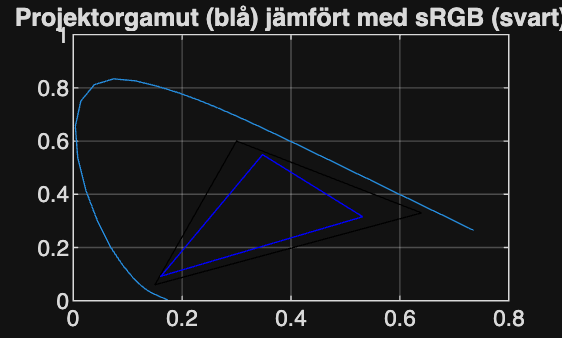

figure;
plot_chrom_sRGB(ACRT);
title('Projektorgamut (blå) jämfört med sRGB (svart)');
grid on;

## 3.6 – Jämför spektra för en patch med liten ΔE

% Ladda data
load('chips20.mat');   % 20x61 reflektans
load('illum.mat');     % CIED65 och waverange

wl = double(waverange(:));
E  = CIED65(:);

% Välj patch med minsta ΔE efter klippning
[bestDE, idx] = min(dE_clip);
fprintf('Vald patch: %d, ΔEab = %.3f\n', idx, bestDE);

Vald patch: 1, ΔEab = 0.034


idx = 1

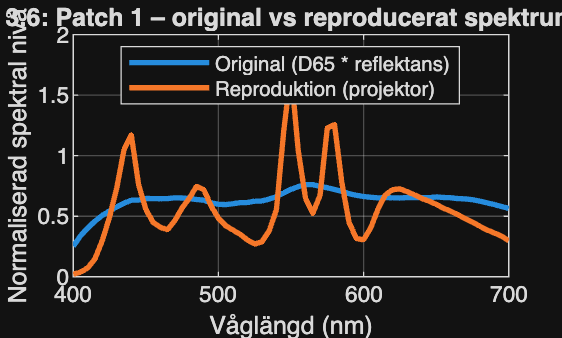


% Originalspektrum under D65
Rchip  = chips20(idx, :)';
S_orig = E .* Rchip;

% Reproducerat spektrum från projektorn
S_proj = S_clip(:, idx);

% Plotta spektra
figure;
plot(wl, S_orig, 'LineWidth', 2); hold on;
plot(wl, S_proj, 'LineWidth', 2);
grid on;
xlabel('Våglängd (nm)');
ylabel('Normaliserad spektral nivå');
title(sprintf('3.6: Patch %d – original vs reproducerat spektrum', idx));
legend('Original (D65 * reflektans)','Reproduktion (projektor)','Location','best');